clear

% (ee) Male
% F0 = 130;   % F0Amp = 1;
% F1 = 270;   F1Amp = db2mag(-4);
% F2 = 2290;  F2Amp = db2mag(-24);
% F3 = 3010;  F3Amp = db2mag(-28);

% % (ae) Female
% F0 = 195;   % F0Amp = 1;
% F1 = 890;   F1Amp = db2mag(-1);
% F2 = 2050;  F2Amp = db2mag(-12);
% F3 = 2810;  F3Amp = db2mag(-22);

% (ah) Male
F0 = 130;   % F0Amp = 1;
F1 = 730;   F1Amp = db2mag(-1);
F2 = 1090;  F2Amp = db2mag(-5);
F3 = 2440;  F3Amp = db2mag(-28);

Fs = 44100;
soundLength = 3; % seconds
numSamples = soundLength * Fs;

fundamental = sin(2 * pi * F0 .* (0:1/Fs:soundLength));
[m,n] = size(fundamental);
noise = wgn(m, n, 0); % amplitude?
% noise = noise / (max(abs(noise)));

[b1, a1] = butter(2, [F1 - F1*0.1,  F1 + F1*0.1 ] / (Fs/2), 'bandpass');
[b2, a2] = butter(2, [F2 - F2*0.07, F2 + F2*0.07] / (Fs/2), 'bandpass');
[b3, a3] = butter(2, [F3 - F3*0.05, F3 + F3*0.05] / (Fs/2), 'bandpass');

dataOut1 = filter(b1, a1, noise);
dataOut2 = filter(b2, a2, noise);
dataOut3 = filter(b3, a3, noise);

% Should this be needed???
dataOut1 = dataOut1 / max(abs(dataOut1));
dataOut2 = dataOut2 / max(abs(dataOut2));
dataOut3 = dataOut3 / max(abs(dataOut3));

% freqz(b1, a1);
% freqz(b2, a2);
% freqz(b3, a3);

mix = fundamental + dataOut1*F1Amp + dataOut2*F2Amp + dataOut3*F3Amp;
mix = mix / (max(abs(mix)));

fadeTime = 0.2; % seconds
fadeVector = linspace(0,1,fadeTime*Fs);
env = [fadeVector, ones(1, length(mix) - 2*length(fadeVector)), fliplr(fadeVector)];
%plot(env);
finalSound = mix .* env;

% plot(mix(:,1:5000));
% plot(noise(:,1:5000));
% plot(dataOut1(:,1:5000));

player = audioplayer(finalSound, Fs);
playblocking(player);

t = (0:1/Fs:soundLength);

fundamental = sin(2 * pi * F0 .* t);

fmDepth = 0.4;
notNoiseHehe = sin( ...
     2*pi*t*F0 + fmDepth*sin( ...
     2*pi*t*F1 + fmDepth*sin( ...
     2*pi*t*F2 + fmDepth*sin(2*pi*t*F3))));
% noise = noise / (max(abs(noise)));

[b1, a1] = butter(2, [F1 - F1*0.1,  F1 + F1*0.1 ] / (Fs/2), 'bandpass');
[b2, a2] = butter(2, [F2 - F2*0.07, F2 + F2*0.07] / (Fs/2), 'bandpass');
[b3, a3] = butter(2, [F3 - F3*0.05, F3 + F3*0.05] / (Fs/2), 'bandpass');

dataOut1 = filter(b1, a1, notNoiseHehe);
dataOut2 = filter(b2, a2, notNoiseHehe);
dataOut3 = filter(b3, a3, notNoiseHehe);

% Should this be needed???
dataOut1 = dataOut1 / max(abs(dataOut1));
dataOut2 = dataOut2 / max(abs(dataOut2));
dataOut3 = dataOut3 / max(abs(dataOut3));

% freqz(b1, a1);
% freqz(b2, a2);
% freqz(b3, a3);

mix = fundamental + dataOut1*F1Amp + dataOut2*F2Amp + dataOut3*F3Amp;
mix = mix / (max(abs(mix)));

fadeTime = 0.2; % seconds
fadeVector = linspace(0,1,fadeTime*Fs);
env = [fadeVector, ones(1, length(mix) - 2*length(fadeVector)), fliplr(fadeVector)];
%plot(env);
finalSound = mix .* env;

% plot(mix(:,1:5000));
% plot(noise(:,1:5000));
% plot(dataOut1(:,1:5000));

player = audioplayer(finalSound, Fs);
playblocking(player);

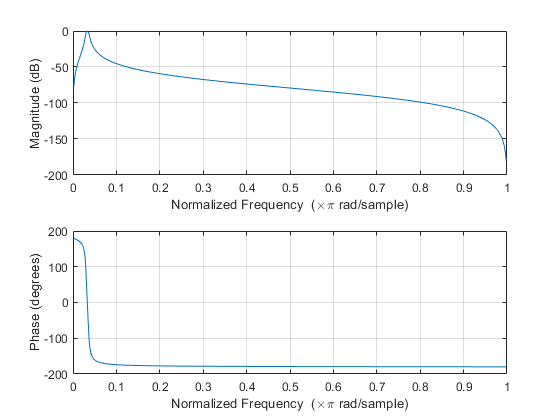

numSin = round(F3/F0) + 10;
sinSum = zeros(1, length(t));

for i=1:numSin
    sinSum = sinSum + sin(2*pi*F0*(i-1) .* t);
end

notNoiseHehe = sinSum;

[b1, a1] = butter(2, [F1 - F1*0.1,  F1 + F1*0.1 ] / (Fs/2), 'bandpass');
[b2, a2] = butter(2, [F2 - F2*0.07, F2 + F2*0.07] / (Fs/2), 'bandpass');
[b3, a3] = butter(2, [F3 - F3*0.05, F3 + F3*0.05] / (Fs/2), 'bandpass');

dataOut1 = filter(b1, a1, notNoiseHehe);
dataOut2 = filter(b2, a2, notNoiseHehe);
dataOut3 = filter(b3, a3, notNoiseHehe);

% Should this be needed???
dataOut1 = dataOut1 / max(abs(dataOut1));
dataOut2 = dataOut2 / max(abs(dataOut2));
dataOut3 = dataOut3 / max(abs(dataOut3));

freqz(b1, a1);

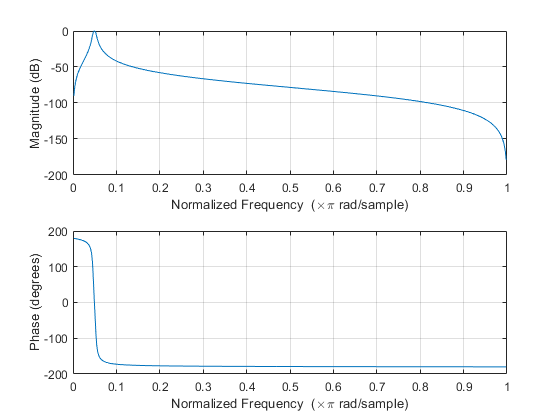

freqz(b2, a2);

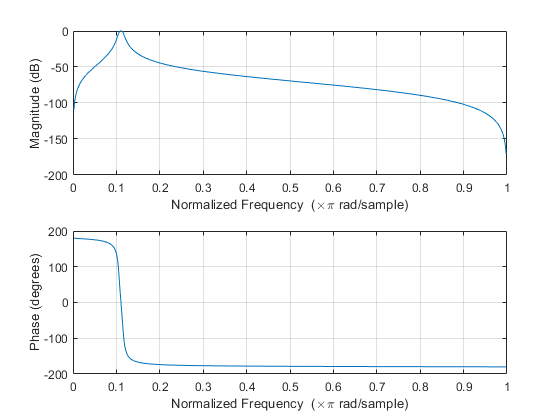

freqz(b3, a3);


frekvensVektor = 1:(-0.05/(length(t)-1)):0.95;
% frekvensVektor = 1:(0.1/(length(t)-1)):1.1;
fundamental = sin(2 * pi * F0 .* frekvensVektor .* t);

mix = fundamental + dataOut1*F1Amp + dataOut2*F2Amp + dataOut3*F3Amp;
mix = mix / (max(abs(mix)));

sus = 0.7;
A = linspace(0, 1, 0.5*Fs);
D = linspace(1, sus, 1.0*Fs);
R = linspace(sus, 0, 0.2*Fs);
S = ones(1, length(t) - length(A) - length(D) - length(R)) * sus;

env = [A, D, S, R];
plot(env);

finalSound = mix .* env;

% plot(mix(:,1:5000));
% plot(noise(:,1:5000));
% plot(dataOut1(:,1:5000));

player = audioplayer(finalSound, Fs);
playblocking(player);


































